% 100 hz 66.*
load cardiac.mat

tok = card(:,1);
len = 50987;

num_tok = 0;
for i = 1:len
    if tok(i, 1) > 0
        num_tok = num_tok + 1;
    end
end

avg_tok = num_tok / (len * 0.01) * 60

avg_tok = 66.0168

local_tok = [];
% step size = 6000
for i = 1:600:len-600
    num_tok = 0;
    for j = i:i+600-1
        if tok(j, 1) > 0
            num_tok = num_tok + 1;
        end
    end
    local_tok = [local_tok num_tok*10];
end

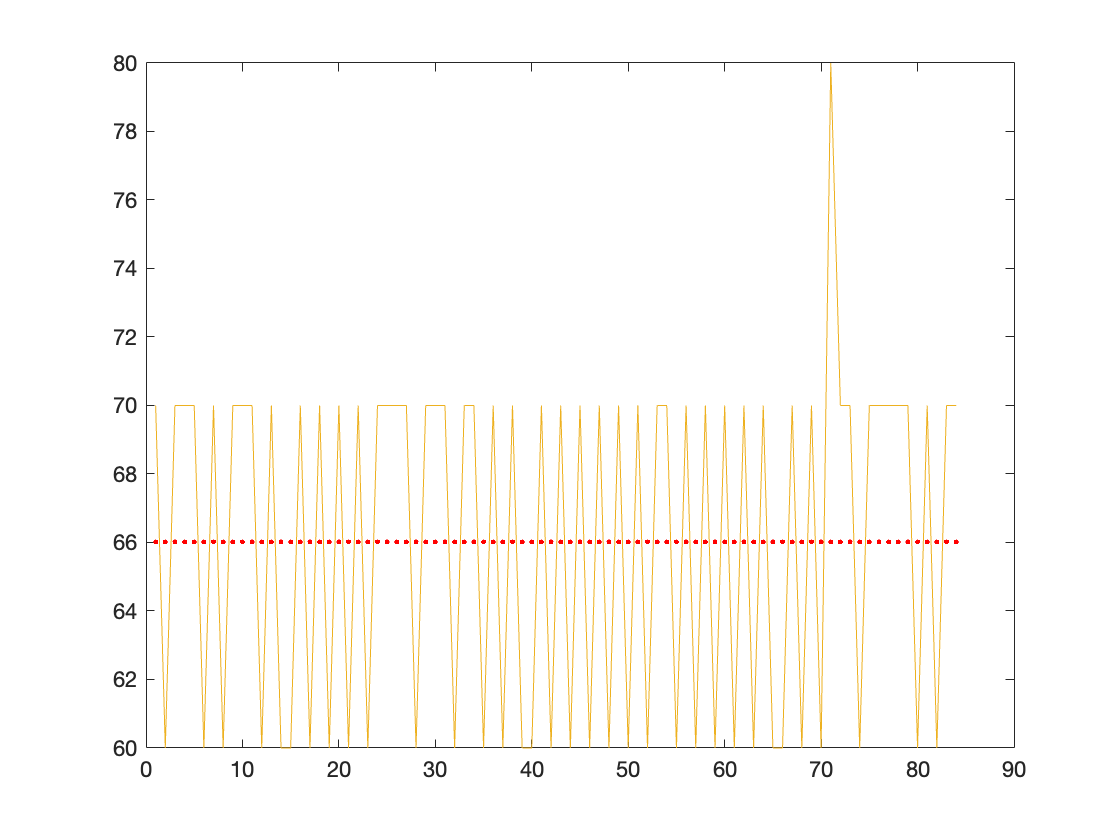

x = 1:84;
x1 = 1:0.5:84;
y1 = interp1(x, local_tok, x1, 'spline');

% plot(x, local_tok, 'o', x1, y1);

plot(local_tok);
hold on;
plot(x, avg_tok, 'r.-');